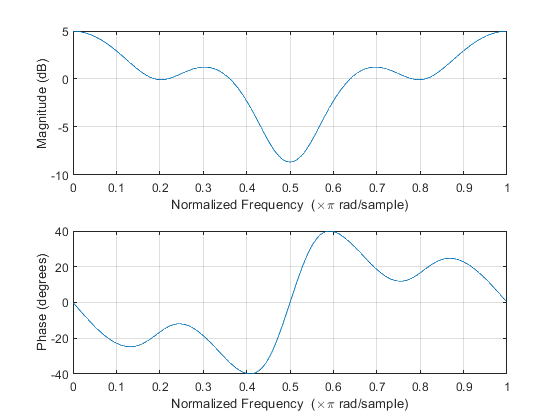

num=[1 0 0.49 0 0 0 0.2401 0 0.0576 0 -0.0282 0 0.0138];
den=[1];
freqz(num,den);

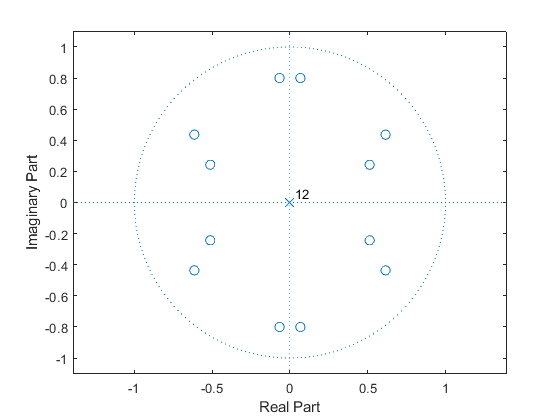

zplane(num,den);

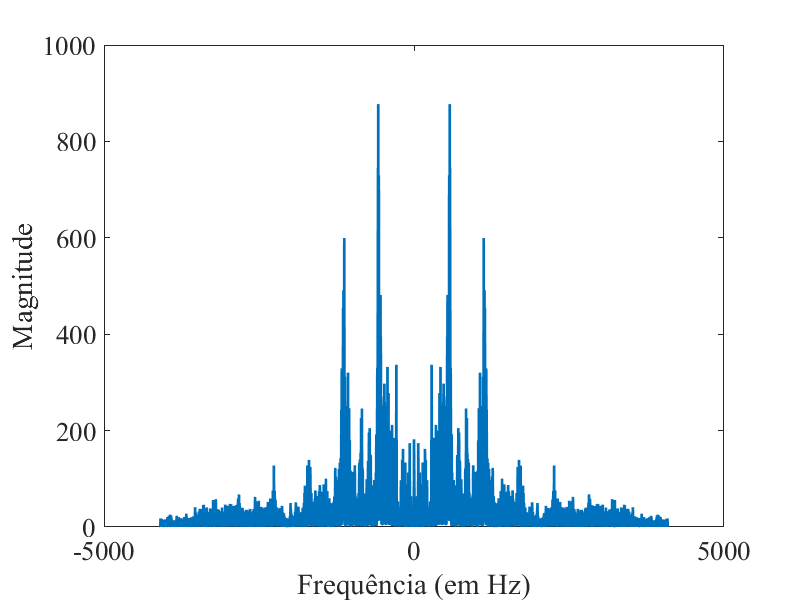

load handel.mat
spectrumAnalyzer(y,Fs);

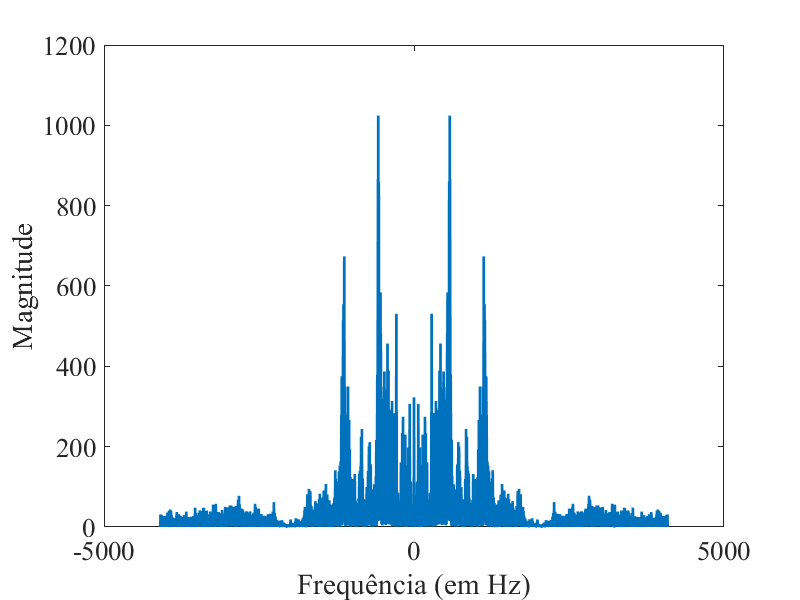

yn=filter(num,den,y);

spectrumAnalyzer(yn,Fs);

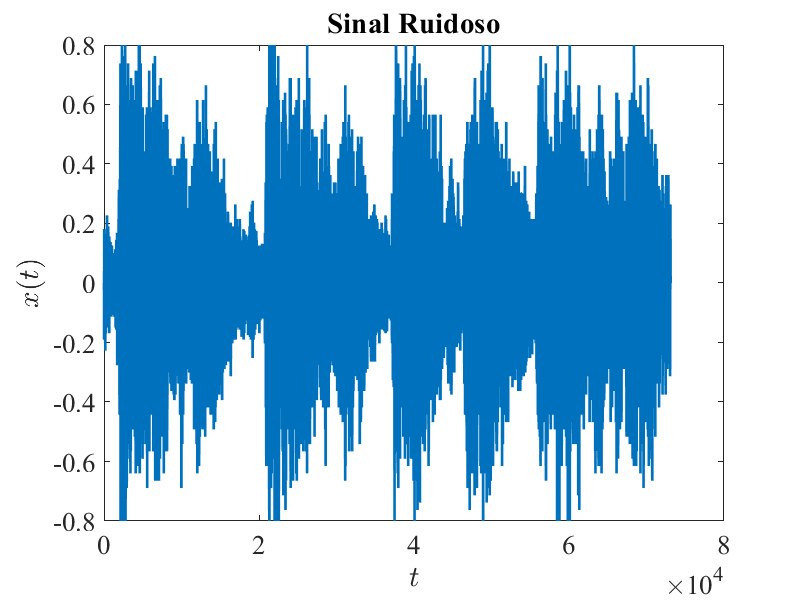

Ts=1/Fs;
t = 0:Ts:5;
plot(y,'linewidth',2)
xlabel('$t$','fontname','times new roman','fontsize',20,'Interpreter','latex');    % Texto do exio x
ylabel('$x(t)$','fontname','times new roman','fontsize',20,'Interpreter','latex'); % Texto do eixo y
title('Sinal Ruidoso','fontname','times new roman','fontsize',20)
%hold on;
set(gca,'fontname','times new roman','fontsize',20); % Ajustando a fonte e o tamanho do nos eixos
%plot(yn,'linewidth',2)
xlabel('$t$','fontname','times new roman','fontsize',20,'Interpreter','latex');    % Texto do exio x
ylabel('$x(t)$','fontname','times new roman','fontsize',20,'Interpreter','latex'); % Texto do eixo y
title('Sinal Ruidoso','fontname','times new roman','fontsize',20)

set(gca,'fontname','times new roman','fontsize',20); % Ajustando a fonte e o tamanho do nos eixos
hold on;

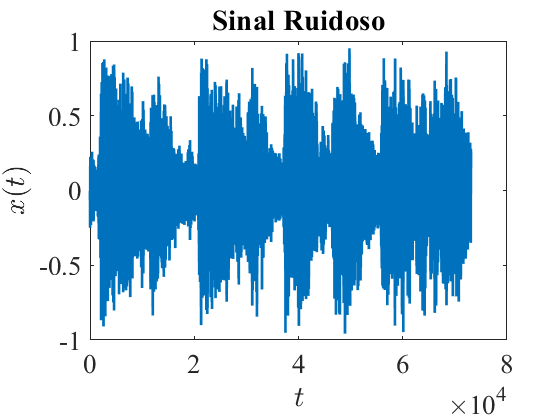

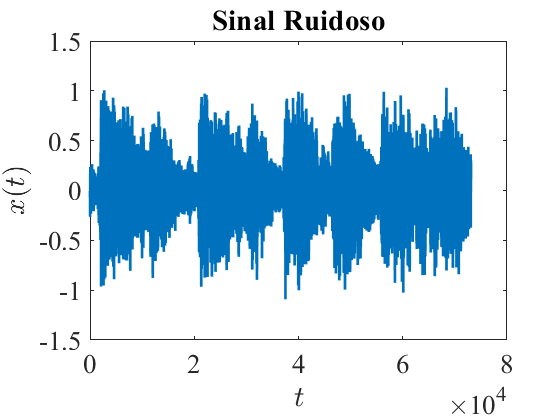

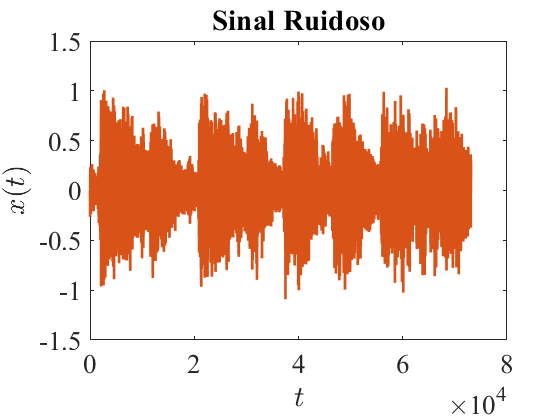

N = [2];

yo = zeros(length(yn),length(N));

for i = 1:length(N)
    b = ones(1,N(i))/N(i);
    yo(:,i) = filter(b,1,yn);
end
figure ; 
plot(yo,'linewidth',2)
xlabel('$t$','fontname','times new roman','fontsize',20,'Interpreter','latex');    % Texto do exio x
ylabel('$x(t)$','fontname','times new roman','fontsize',20,'Interpreter','latex'); % Texto do eixo y
title('Sinal Ruidoso','fontname','times new roman','fontsize',20)
set(gca,'fontname','times new roman','fontsize',20); % Ajustando a fonte e o tamanho do nos eixos